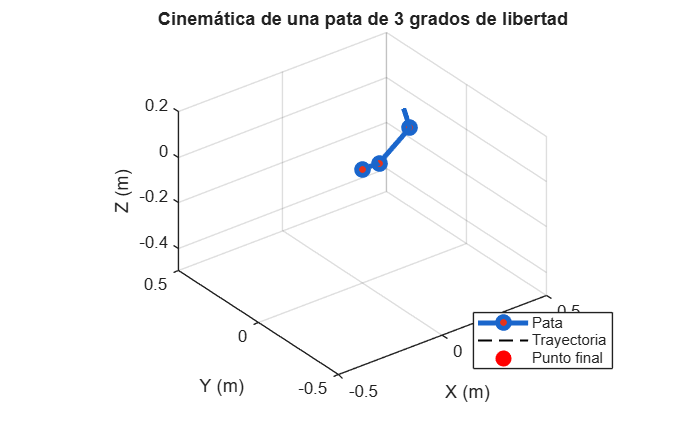

%Longitudes de la pata
L1 = 0.08;   % Coxa
L2 = 0.18;   % Femur
L3 = 0.20;   % Tibia

% Trayectorias articulares
t = linspace(0, 2*pi, 360);
q1 = deg2rad(25*sin(t));              % Rotación de la coxa
q2 = deg2rad(35 + 15*sin(t));         % Ángulo del femur
q3 = deg2rad(55 + 20*sin(t + pi/3));  % Ángulo de la tibia

% Cinemática directa
p0 = zeros(3, numel(t));

p1 = [L1*cos(q1);
      L1*sin(q1);
      zeros(size(t))];

p2 = p1 + [L2*cos(q2).*cos(q1);
           L2*cos(q2).*sin(q1);
           L2*sin(q2)];

p3 = p2 + [L3*cos(q2 + q3).*cos(q1);
           L3*cos(q2 + q3).*sin(q1);
           L3*sin(q2 + q3)];

% Configuración de la gráfica
figure('Color','w');
hold on; grid on; axis equal;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Cinemática de una pata de 3 grados de libertad');
view(3)
xlim([-0.5 0.5]);
ylim([-0.5 0.5]);
zlim([-0.5 0.2]);

trayectoria = plot3(p3(1,:), p3(2,:), p3(3,:), ...
    'k--', 'LineWidth', 1.2);

pata = plot3(nan, nan, nan, 'o-', ...
    'LineWidth', 3, 'MarkerSize', 7, ...
    'Color', [0.1 0.4 0.8], ...
    'MarkerFaceColor', [0.9 0.2 0.1]);

puntoFinal = plot3(nan, nan, nan, 'ro', ...
    'MarkerSize', 9, 'MarkerFaceColor', 'r');

legend([pata, trayectoria, puntoFinal], ...
    {'Pata', 'Trayectoria', 'Punto final'}, ...
    'Location', 'best');

% Animación
for k = 1:numel(t)
    set(pata, ...
        'XData', [p0(1,k) p1(1,k) p2(1,k) p3(1,k)], ...
        'YData', [p0(2,k) p1(2,k) p2(2,k) p3(2,k)], ...
        'ZData', [p0(3,k) p1(3,k) p2(3,k) p3(3,k)]);

    set(puntoFinal, ...
        'XData', p3(1,k), ...
        'YData', p3(2,k), ...
        'ZData', p3(3,k));

    drawnow;
end